## Cambridge NeuroTech E1 Probe Map

#### Need map from probe site to TDT A/D channel using Cambridge NeuroTech Samtec to Omnetics converter and TDT Omnetics to ZIF (or TDT customized chronic 16 channel Omnetics headstage)

These data will be used to define a .prb file for use with spike sorting programs (e.g., spyKING CIRCUS)

## Define Probe

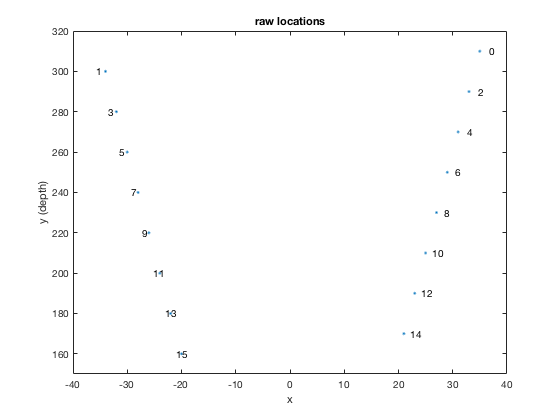

%% specifications for E-16 probe from Cambridge NeuroTech
% Store specs in a struct, prb
% index to sites (probably unnecessary)
prb.index = 15:-1:0;
% # of sites on probe
prb.nsites = 16;
% xy coordinates of sites, with x location in 1st column, y location
% (increasing depth as value increases) in 2nd column. units are arbitrary,
% but could be um...
% this is as specd in file CNT_E1_Klusta.txt provided by Tahl Holtzman of
% Cambridge NeuroTech 
prb.xy_klusta = [ ...
-20, 160; ...
21, 170; ...
-22, 180; ...
23, 190; ...
-24, 200; ...
25, 210; ...
-26, 220; ...
27, 230; ...
-28, 240; ...
29, 250; ...
-30, 260; ...
31, 270; ...
-32, 280; ...
33, 290; ...
-34, 300; ...
35, 310; ...
];

%% plot the locations as 'o's with site index text adjacent
plot(prb.xy_klusta(:, 1), prb.xy_klusta(:, 2), '.')
text(prb.xy_klusta(:, 1)*(1 + 0.05), prb.xy_klusta(:, 2), num2cell(prb.index))
ylim([150 320])
xlabel('x')
ylabel('y (depth)')
title('raw locations')

### Probe site ID map:

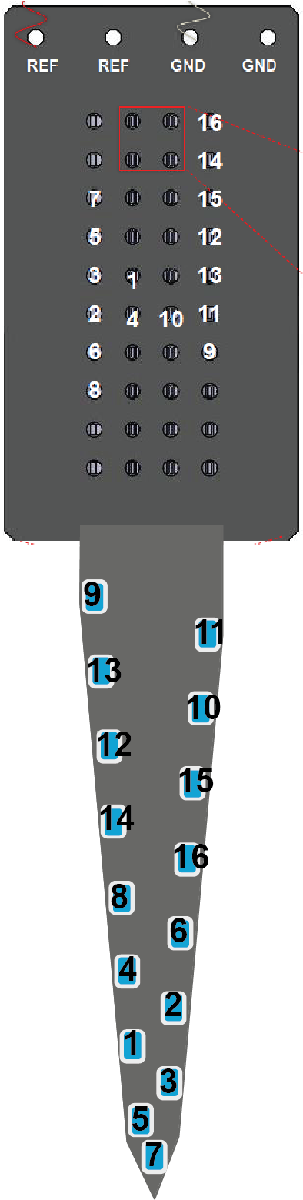

% probe site ID from probe layout pdf: 
%    CambridgeNeuroTech_Acute16ChProbe_Pinouts.pdf
% data also in E1_ProbeLayout.xls
%
% *** these sites are listed from proximal (top of probe) to
% *** distal (tip of probe)
prb.id = [ ...
	9; ...
	11; ...
	13; ...
	10; ...
	12; ...
	15; ...
	14; ...
	16; ...
	8; ...
	6; ...
	4; ...
	2; ...
	1; ...
	3; ...
	5; ...
	7	];


### Site ID in order of depth

% print out in mock layout
for n = 1:prb.nsites
	if isodd(n)
		fprintf('   %d\n', prb.id(n));
	else
		fprintf('      %d\n', prb.id(n));
	end
end

   9


      11


   13


      10


   12


      15


   14


      16


   8


      6


   4


      2


   1


      3


   5


      7


### define probe site (column 1) to AD channel (column 2) map:

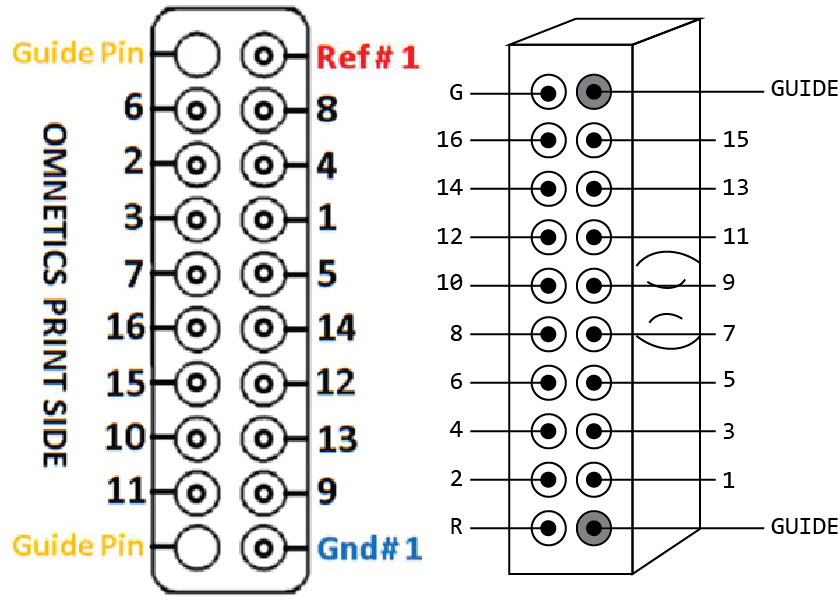

prb.id_to_channel_map = [ ...
	6,	15; ...
	2,	13; ...
	3,	11; ...
	7,	9; ...
	16,	7; ...
	15,	5; ...
	10,	3; ...
	11,	1; ...
	8,	16; ...
	4,	14; ...
	1,	12; ...
	5,	10; ...
	14,	8; ...
	12,	6; ...
	13,	4; ...
	9,	2 ];

%% for each probe_id site, find the corresponding A/D channel
% so, loop through the sites as listed in prb.id...
prb.channel = zeros(prb.nsites, 1);
for n = 1:prb.nsites
	% find location of this id in prb.site_to_channel_map first column
	indx = find(prb.id(n) == prb.id_to_channel_map(:, 1));
	% matching AD channel will be in second column
	prb.channel(n) = prb.id_to_channel_map(indx, 2);
	fprintf('site %d --> chan %d\n', prb.id(n), ...
						prb.channel(n));
end

site 9 --> chan 2
site 11 --> chan 1
site 13 --> chan 4
site 10 --> chan 3
site 12 --> chan 6
site 15 --> chan 5
site 14 --> chan 8
site 16 --> chan 7
site 8 --> chan 16
site 6 --> chan 15
site 4 --> chan 14
site 2 --> chan 13
site 1 --> chan 12
site 3 --> chan 11
site 5 --> chan 10
site 7 --> chan 9


## need to do some tweaking to get sites/channels to line up and match physical layout of probe

%% what we need: 
% A/D channels mapped to x, y locations of recording probe sites.
% right now locations are listed from bottom to top, so flip up down
xyud = flipud(prb.xy_klusta)

xyud =     35   310
   -34   300
    33   290
   -32   280
    31   270
   -30   260
    29   250
   -28   240
    27   230
   -26   220


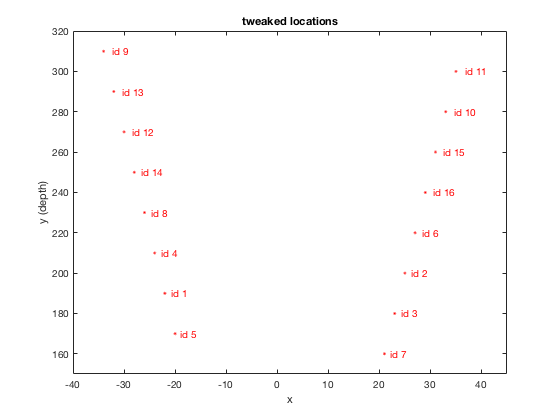

% then need to reverse the xy coords in pairs
xylr = zeros(size(xyud));
for n = 1:2:prb.nsites
	xylr(n, 1) = xyud(n+1, 1);
	xylr(n+1, 1) = xyud(n, 1);
	xylr(n, 2) = xyud(n, 2);
	xylr(n+1, 2) = xyud(n+1, 2);
end
% plot xy coordinates and site id
figure(2)
plot(xylr(:, 1), xylr(:, 2), '.r')
ctxt = cell(length(prb.id), 1);
for n = 1:length(prb.id)
    ctxt{n} = sprintf('id %d', prb.id(n));
    if xylr(n, 1) < 0
        text(xylr(n, 1)*(1 - 0.05), xylr(n, 2), ctxt{n}, 'Color', 'r')
    else
        text(xylr(n, 1)*(1 + 0.05), xylr(n, 2), ctxt{n}, 'Color', 'r')
    end
end
xlim([-40 45])
ylim([150 320])
xlabel('x')
ylabel('y (depth)')
title('tweaked locations')

locations now match the physical locations on the probe and are in same order as prb.id.

% Store "tweaked" physical xy locations
prb.xy = xylr;

### Now, need to map A/D channel to physical location

prb.channel_to_xy_map = [prb.channel prb.xy];

## Create table to hold map

prb.probetable = table(prb.id, prb.channel, prb.xy, 'VariableNames', {'SiteID', 'ADchannel', 'XY'});

## Write to mat file

save('CNT_E1_probestruct.mat', 'prb', '-MAT');

## Write channel and xy locations in prb format

sample:

% probe file filename
% prbfile = 'CNT_E1.prb';

% open file
fp = 1;
% write header
fprintf(fp, '# SpyKING CIRCUS .prb configuration file\n');
fprintf(fp, '# for Cambridge NeuroTech E1 16 channel probe\n')
fprintf(fp, '# Date: %s\n', date)
%{
total_nb_channels = 30
radius            = 200
channel_groups    = {}

channel_groups = {
    # Shank index.
    1:
        {   
            'channels': list(range(30)),
            'geometry': {
                0: (0, -1050),
                1: (22, -1050),
                2: (0, -1072),
                3: (22, -1072),
                4: (0, -1094),
                5: (22, -1094),
                6: (0, -1116),
                7: (22, -1116),
                8: (0, -1138),
                9: (22, -1138),
                10: (0, -1160),
                11: (22, -1160),
                12: (0, -1182),
                13: (22, -1182),
                14: (0, -1204),
                15: (22, -1204),
                16: (0, -1226),
                17: (22, -1226),
                18: (0, -1248),
                19: (22, -1248),
                20: (0, -1270),
                21: (22, -1270),
                22: (0, -1292),
                23: (22, -1292),
                24: (0, -1314),
                25: (22, -1314),
                26: (0, -1336),
                27: (22, -1336),
                28: (0, -1358),
                29: (22, -1358),
            }
    }
}

%}